# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

Two limitations of the Fourier-transformbased frequency representation were also discussed: 

- changes in frequency structure over time are difficult to visualize

- EEG data violate the stationarity assumption of Fourier analysis. 

**These two limitations provide motivation to apply time-resolved frequency decomposition of EEG data.  **

The next six chapters introduce you to several of the most commonly used methods for obtaining time-resolved frequency representations (or time-frequency representations) of EEG data.  

### Convlution theorom

Convolution in the time domain is the same as multiplication in the frequency domain. (The opposite is also true, although it is less relevant for EEG data analyses: convolution in the frequency domain is the same as multiplication in the time domain.)

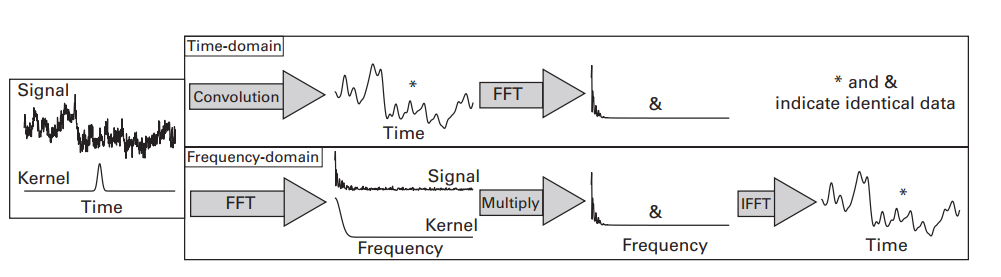

srate = 1000;
time  = -.5:1/srate:.5-1/srate;
f     = 20;
fg    = [15 5];
s     = sin(2*pi*f*time);

for i=1:2
    
    % compute Gaussian
    g = exp((-time.^2)/(2*(4/(2*pi*fg(i))^2)))/fg(i);
    
    
    figure
    
    subplot(411)
    plot(time,s)
    title('Sine wave (signal)')
    set(gca,'ylim',[-1.1 1.1])
    
    subplot(412)
    plot(time,g)
    title('Gaussian (kernel)')
    
    subplot(413)
    plot(time,conv(s,g,'same'))
    set(gca,'ylim',[-1.1 1.1])
    title('result of convolution')
    
    subplot(427)
    fft_s = abs(fft(s));
    fft_s = fft_s(1:floor(length(fft_s)/2)+1)./max(fft_s(1:floor(length(fft_s)/2)+1));
    bar(0:500,fft_s,'r')
    hold on
    
    fft_g = abs(fft(g));
    fft_g = fft_g(1:floor(length(fft_g)/2)+1)./max(fft_g(1:floor(length(fft_g)/2)+1));
    plot(0:500,fft_g)
    set(gca,'xlim',[0 40],'ylim',[0 1.05])
    title('individual power spectra')
    
    subplot(428)
    bar(0:500,fft_g.*fft_s)
    set(gca,'xlim',[0 40],'ylim',[0 .035])
    title('multiplied power spectra')
end

% inset scaling: axis([15 25 -.01 .11])


Convolving EEG time series

% create Gaussian
load sampleEEGdata
eegdat4convol = squeeze(EEG.data(47,:,1));
time = -1:1/EEG.srate:1;
s = 5/(2*pi*30);
gaussian = exp((-time.^2)/(2*s^2))/30;

figure

% plot EEG data
subplot(411)
plot(EEG.times,eegdat4convol)

% plot Gaussian
subplot(412)
plot(time,gaussian)

% plot result of convolution
subplot(413)
plot(EEG.times,eegdat4convol,'r')
hold on
plot(EEG.times,conv(eegdat4convol,gaussian,'same'))

subplot(427)
nfft = length(eegdat4convol);
fft_s = abs(fft(eegdat4convol,nfft));
fft_s = fft_s(1:floor(nfft/2)+1);
f = linspace(0,EEG.srate/2,floor(nfft/2)+1);
plot(f,fft_s./max(fft_s),'r')
hold on

fft_g = abs(fft(gaussian,nfft));
fft_g = fft_g(1:floor(nfft/2)+1);
plot(f,fft_g./max(fft_g))

set(gca,'xlim',[0 60])

subplot(428)
plot(f,fft_s.*fft_g)
set(gca,'xlim',[0 60])

### Exercise

- watch this video frist : [https://www.youtube.com/watch?v=4TTpwIZrUAo](https://www.youtube.com/watch?v=4TTpwIZrUAo)

- Use sample_EEG data. First, perform time-domain convolution using the “ manual ” convolution method. Second, perform frequency-domain convolution using the discrete time Fourier transform presented at the beginning of this chapter. Finally, perform frequency-domain convolution using the Matlab functions fft and ifft (do not use the function conv).

### Overview to time-resolved frequency

load sampleEEGdata
time = -1:1/EEG.srate:1;
f = 4; % frequency of sine wave in Hz
figure
subplot(511)
plot(squeeze(EEG.data(47,:,1)))
axis tight

subplot(512)
sine_wave = cos(2*pi*12.*time);
plot(sine_wave)
axis tight

subplot(513)
% boxcar envelope
boxcar = zeros(size(sine_wave));
midpoint = (length(time)-1)/2;
boxcar(midpoint-round(EEG.srate/12/5):midpoint+round(EEG.srate/12/1.25)) = 1;
plot(sine_wave.*boxcar)
axis tight

subplot(514)
% boxcar envelope
boxcar = zeros(size(sine_wave));
midpoint = (length(time)-1)/2;
boxcar(midpoint-50:midpoint+50) = 1;
plot(sine_wave.*boxcar)
axis tight

subplot(515)
% redefine gaussian for new sine wave
s=1.5/(2*pi*12); gaussian_win = exp(-time.^2./(2*s^2));
plot(time,sine_wave.*gaussian_win)
axis tight

### **Morlet Wavelets and Wavelet Convolution**  

Wavelets must have values at or very close to zero at both ends**, and they must have a mean value of zero.   **

A Morlet wavelet looks like a sine wave in the middle but then tapers off to zero at both ends.   

**A sine wave windowed with a Gaussian is called a Morlet wavelet.**

The variable *a *refers to amplitude (the height of the Gaussian), *t *is time, *m *is an *x*-axis offset (this is not relevant for EEG analyses and can always be set to zero and thus left out of the equation), and *s *is the standard deviation or the width of the Gaussian. 

The variable *f *is frequency (in hertz), and *n *refers to the number of wavelet cycles.  The variable *f *is frequency (in hertz), and *n *refers to the number of wavelet cycles.   

% Lets practice

srate = 500; % sampling rate in Hz
f = 10; % frequency of the sine wave in Hz
time = -1:1/srate:1; % time, from -1 to 1 second in steps of 1/sampling-rate
a = 1;
sine_wave = exp(1i*2*pi*f.*time);
s= 6.5/(2*pi*f);
gaussian_win = a * exp((-time.^2)/(2*s^2));

subplot(3,1,1)
plot(time, sine_wave);
subplot(3,1,2)
plot(time, gaussian_win);
subplot(3,1,3)
plot(time, sine_wave.*gaussian_win);


% make plots containing each component
% sine_wave = exp(2*pi*1i*f.*time); % complex wavelet
% s=6/(2*pi*f);
% gaussian_win = exp(-time.^2./(2*s^2));
% 
% % and together they make a wavelet!
% wavelet = sine_wave .* gaussian_win;
figure
subplot(311)
plot(time,real(sine_wave)) % only plot the real component... we�ll learn about this later
title('Sine wave')

subplot(312)
plot(time,gaussian_win) % plots the Gaussian window
title('Gaussian window')
 
subplot(313)
plot(time,real(wavelet)); % plots the wavelet
title('My first wavelet!')
xlabel('Time (ms)')

The stationarity assumption of wavelet convolution is that t**he signal is stationary only during the time period in which the wavelet looks like a sine wave. **This is a more reasonable assumption that is likely to be valid: EEG data often remain stationary for hundreds of milliseconds (Florian and Pfurtscheller 1995; Jeong, Gore, and Peterson 2002).   

- Similar to the way a Fourier transform uses many sine waves of different frequencies, time-frequency decomposition via wavelet convolution involves using many wavelets of different frequencies. 

- Unlike Fourier analysis, however, the frequencies of the wavelet can be specified by you rather than being specified by the number of data points in the time series. 

- Furthermore, the number of wavelets that can be used is not constrained—you can use as many wavelets as you want, and those wavelets can have almost any frequency you specify. 

- A group of wavelets that share the same properties but differ in frequency is called a family of wavelets. 

**There are a few theoretical and practical limits to constructing a family of wavelets:**

- You cannot use frequencies that are slower than your epochs. That is, if you have 1 s of data, you cannot analyze activity lower than 1 Hz. In practice, you should have several cycles of activity (for example, if you have 1 s of data, use wavelets that are 4 Hz and faster).

- The frequencies of the wavelets cannot be above the Nyquist frequency (one-half of the sampling rate).

- Because of frequency smoothing from time-frequency precision trade-offs (this is discussed and demonstrated in the next chapter), frequencies that are very close to each other will likely provide similar or nearly identical results. For example, if you have a wavelet at 15.0 Hz, a wavelet at 14.9 Hz is unlikely to provide any unique information. More frequency bins may produce smoother-looking plots but will also increase computation time without increasing the information in the results. In general, between 15 and 30 frequencies (spanning, say, 3 Hz to 60 Hz) should be sufficient for most experiments  

num_wavelets      =  80;  % number of frequency bands
lowest_frequency  =   2;  % in Hz
highest_frequency = 100;  % in Hz

srate = 500;
time = -1:1/srate:1;
frequencies=linspace(lowest_frequency,highest_frequency,num_wavelets);
% note: the "linspace" function creates linearly spaced numbers between the first and second 
% inputs, with the number of steps corresponding to the third input. 
figure, plot(frequencies,'-*')
xlabel('Frequency order')
ylabel('Frequency in Hz')


% initialize wavelet family
wavelet_family = zeros(num_wavelets,length(time));
 
% Loop through frequencies and make a family of wavelets.
for fi=1:num_wavelets
    
    % create a sine wave at this frequency
    sinewave = exp(2*1i*pi*frequencies(fi).*time); % the "1i" makes it a complex wavelet
    
    % create a Gaussian window
    gaus_win = exp(-time.^2./(2*(6/(2*pi*frequencies(fi)))^2));
    
    % create wavelet via element-by-element multiplication of the sinewave and gaussian window
    wavelet_family(fi,:) = sinewave.*gaus_win;
    
    % note that you can also do this on one line:
    wavelet_family(fi,:) = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*(6/(2*pi*frequencies(fi)))^2));
end

% Plot a few wavelets
figure
subplot(2,1,1)
plot(time,real(wavelet_family(1:round(rand*30):end,:))') 
title('A few wavelets...')
 
% Note that in the subplot command you don't need commas if you have fewer than 10 
% rows/cols and if you are not using any variables.
subplot(212)
plot(time,real(wavelet_family(30,:)))
hold on
plot(time,imag(wavelet_family(30,:)),':')
title('Real and imaginary parts of one wavelet')
legend({'real';'imaginary'})


% finally, image the wavelet family.
figure
imagesc(time,frequencies,real(wavelet_family))
axis xy % equivalent to "set(gca,'ydir','normal')
xlabel('Time (s)')
ylabel('Frequency (Hz)')

Now lets create vedio

figure, set(gcf,'color','k')
surf(repmat(real(wavelet_family),2,1))
shading interp
axis off
axis([0 length(time) -20 21 -1 1])
view([ -4 4 ])
 
for i=4:2:90
    view([ -4 i ])
    pause(.1)
end
 
rotate3d


### **Wavelet Convolution as a Bandpass Filter**  

Morlet wavelet has a Gaussian shape around the peak frequency of the wavelet  

Thats why its a Band Pass filter

load sampleEEGdata
eegdata = squeeze(EEG.data(47,:,10));

% create wavelet
time = -1:1/EEG.srate:1;
f = 6; % frequency of sine wave in Hz
sine_wave = exp(1i*2*pi*f.*time);
s = 4.5/(2*pi*f); 
gaussian_win = exp(-time.^2./(2*s^2));
wavelet = sine_wave .* gaussian_win;
% half of the wavelet size, useful for chopping off edges after convolution.
halfwaveletsize = ceil(length(wavelet)/2);

% convolve with data
% compute Gaussian
n_conv = length(wavelet) + EEG.pnts - 1;

fft_w = fft(wavelet,n_conv);
fft_e = fft(eegdata,n_conv);
ift   = ifft(fft_e.*fft_w,n_conv)*sqrt(s)/10; % sqrt... is an empirical scaling factor that works here
wavelet_conv_data = real(ift(halfwaveletsize:end-halfwaveletsize+1));

% create filter and apply to data 
% (more on how to interpret this code in a few chapters!)
nyquist       = EEG.srate/2;
transition_width = 0.2; % percent
filter_low    = 4; % Hz
filter_high   = 8; % Hz
ffrequencies  = [ 0 filter_low*(1-transition_width) filter_low filter_high filter_high*(1+transition_width) nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(round(3*(EEG.srate/filter_low)),ffrequencies,idealresponse);
eeg_4to8      = filtfilt(filterweights,1,double(eegdata));



% now plot all the pieces
figure

plot(EEG.times,eegdata)
hold on
plot(EEG.times,wavelet_conv_data,'r','linew',2)
plot(EEG.times,eeg_4to8,'m','linew',2)
set(gca,'xlim',[-200 1200],'ydir','r')
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
legend({'Raw data';'wavelet convolved';'band-pass filtered'})

## Three Steps of Wavelet Convolution

- **Take fft Signal (EEG data, wavelet)**

- **Multiply Fourie spectra**

- **Take iFFT**

% Lets practice
clear 
% calling the data
load('sampleEEGdata.mat');
data = EEG.data(2,:,4);
srate = EEG.srate;
time = -2:1/srate:2;
f = 8;

% making the wavelet
sine_wave = exp(2*pi*1i*f.*time); % complex wavelet
s=6/(2*pi*f);
gaussian_win = exp(-time.^2./(2*s^2));
wavelet = sine_wave .* gaussian_win;

% Take fft
nlength_data = length(data);
nlength_wave = length(wavelet);
n_conv = nlength_data + nlength_wave - 1;

wave_ff = fft(wavelet,n_conv);
wave_ff_sc = wave_ff./max(wave_ff);

data_ff = fft(data, n_conv);

% Multiply

output = data_ff.*wave_ff_sc;





### **Exercises**

1. Create a family of Morlet wavelets ranging in frequency from 2 Hz to 30 Hz in five steps.

2. Select one electrode from the scalp EEG dataset and convolve each wavelet with EEG data from all trials from that electrode. Apply the Matlab function real to the convolution result, as in convol_result=real(convol_result). This will return the EEG data bandpass filtered at the peak frequency of the wavelet. You learn more about why this is in the next chapter.

3. Average the result of convolution over all trials and plot an ERP corresponding to each wavelet frequency. Each frequency should be in its own subplot.

4. Plot the broadband ERP (without any convolution). Thus, you will have six subplots in one figure. How do the wavelet-convolved ERPs compare with the broadband ERP? Are there dynamics revealed by the wavelet-convolved ERPs that are not apparent in the broadband ERP, and are there dynamics in the broadband ERP that are not apparent in the waveletconvolved ERPs? Base your answer on qualitative visual inspection of the results; statistics or other quantitative comparisons are not necessary